# Bayesian tomography

**Author**: Abakumov Ivan

**Publication date**: 15th Feb 2018

## Introduction

for the purpose of education

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Define grid and velocity model

% Make G-file
G=GridClass;

%    [m]        [m]       [m]          [s]
G.x0=-150;     G.y0=0;    G.z0=250;    G.t0 = 0.00;            % initial point
G.nx=201;      G.ny=1;    G.nz=201;    G.nt = 300;             % grid size
G.dx=1.5;      G.dy=0;    G.dz=1.5;    G.dt = 0.001;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-150, dx=1.5, Nx=201.
y0=0, dy=0, Ny=1.
z0=250, dz=1.5, Nz=201.
t0=0, dt=0.001, Nt=300.


G.setGrid;
Gold=G.oldGrid;


[XX, ZZ] = meshgrid(G.xx, G.zz);

## Acquisition

acq.sx = [-150 -150 -150 -150 -150 -150 -150 -100 -50 0    50 100 150 150 150 150 150 150 150 100 50    0 -50 -100];
acq.sz = [ 250  300  350  400  450  500  550  550 550 550 550 550 550 500 450 400 350 300 250 250 250 250 250  250];

acq.rx = [-150 -150 -150 -150 -150 -150 -150 -100 -50 0    50 100 150 150 150 150 150 150 150 100 50    0 -50 -100];
acq.rz = [ 250  300  350  400  450  500  550  550 550 550 550 550 550 500 450 400 350 300 250 250 250 250 250  250];

acq.gsx = x2grid(acq.sx, G.x0, G.dx, G.nx); 
acq.gsz = x2grid(acq.sz, G.z0, G.dz, G.nz); 
acq.grx = x2grid(acq.rx, G.x0, G.dx, G.nx); 
acq.grz = x2grid(acq.rz, G.z0, G.dz, G.nz);

## True velocity model

tvelmod = zeros(G.nx, G.nz); 
for i=1:G.nx
    tvelmod(i,:) = 2000 + 1.25*G.dx*i; 
end

tvelmod(33:100, 33:74) = 3000; 
tvelmod(100:167, 127:167) = 1500; 



figure(1)

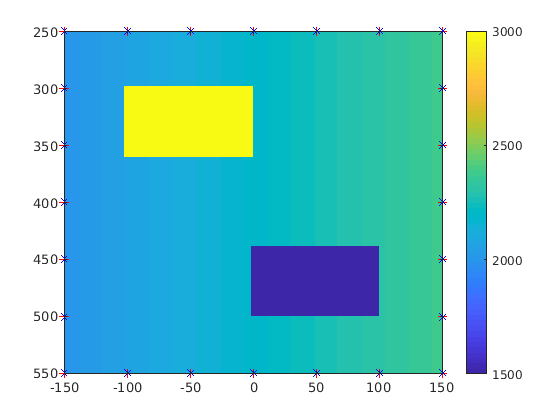

imagesc(G.xx, G.zz, tvelmod'); 
hold on
 colorbar;
plot(acq.sx, acq.sz, 'r*')
plot(acq.rx, acq.rz, 'bx')

## Calculate exact traveltimes

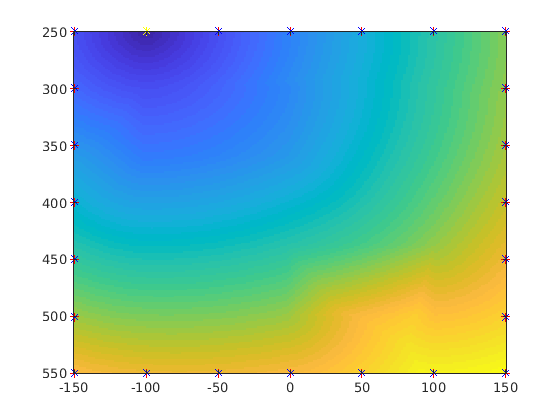

nshot = length(acq.sx); 
nrece = length(acq.rx); 

texact = zeros(nshot, nrece); 

for s=1:nshot
    S = [ acq.sx(s) acq.sz(s)];
    tti  = FSM2D(Gold,S,tvelmod); 
    for r=1:nrece
        texact(s,r) = tti(acq.grx(r), acq.grz(r));  
    end
end

sigma = 0.001; 
noise = sigma*randn(size(texact));
texact = texact + noise;


figure(2)
imagesc(G.xx, G.zz, tti');
hold on
plot(acq.sx, acq.sz, 'r*')
plot(acq.rx, acq.rz, 'bx')
plot(acq.sx(s), acq.sz(s), 'y*')

## Parameters

number_of_cells = 40; 
number_of_parameters=3*number_of_cells;
number_of_particles=1000;   
number_of_iterations=10000;   

XMIN = G.x0; XMAX = G.mx;
ZMIN = G.z0; ZMAX = G.mz; 
VMIN = 1000; VMAX = 4000; 

Xmin = [XMIN*ones(number_of_cells,1);ZMIN*ones(number_of_cells,1);VMIN*ones(number_of_cells,1)];
Xmax = [XMAX*ones(number_of_cells,1);ZMAX*ones(number_of_cells,1);VMAX*ones(number_of_cells,1)]; 
Vmax = [(XMAX-XMIN)/100*ones(number_of_cells,1);...
        (ZMAX-ZMIN)/100*ones(number_of_cells,1);...
        (VMAX-VMIN)/100*ones(number_of_cells,1)];  

Vmin = - Vmax; 
    
saveF = zeros(number_of_iterations,number_of_particles);
saveX = zeros(number_of_parameters,number_of_particles);


number_of_iterations = 4000;
tic
[saveF, saveX] = make_markov_chain(G,acq,XX,ZZ,texact,sigma,Xmin,Xmax,Vmin,Vmax,number_of_parameters,number_of_iterations)

saveF = 	1.0e+-3 *

    0.0010
    0.0013
    0.0012
    0.0013
    0.0012
    0.0013
    0.0011
    0.0009
    0.0009
    0.0009


saveX = 	1.0e+03 *

    0.0620    0.0691    0.0959    0.1025   -0.0385    0.0978   -0.0263   -0.0509    0.0056   -0.0759    0.0446   -0.1346   -0.0616    0.0052    0.1281    0.0575   -0.0003   -0.0749    0.0585    0.0055   -0.1244    0.1372    0.1148    0.0272    0.0588   -0.0900   -0.0319   -0.1101    0.0812    0.1232    0.0184    0.0872   -0.0211    0.1448    0.0029    0.0126    0.1078    0.0063   -0.0483   -0.0755    0.3260    0.3563    0.2853    0.3611    0.2591    0.4596    0.3824    0.2918    0.3593    0.2869
    0.0626    0.0680    0.0950    0.0996   -0.0413    0.0951   -0.0266   -0.0528    0.0053   -0.0740    0.0470   -0.1341   -0.0586    0.0028    0.1280    0.0581    0.0009   -0.0766    0.0607    0.0062   -0.1247    0.1356    0.1162    0.0287    0.0588   -0.0880   -0.0307   -0.1106    0.0831    0.1254    0.0169    0.0889   -0.0208    0.1439    0.0010    0.0143    0.1080    0.0072   -0.0467   -0.0768    0.3266    0.3550    0.2849    0.3627    0.2594    0.4604    0.3796    0.289

toc

Elapsed time is 612.531523 seconds.


## Visualize results

meanV = zeros(size(tvelmod)); 
stdV = zeros(size(tvelmod)); 
F = saveF(end,:);
W = exp(-F.^2/2);       % likelyhood

for i=1:1000
    Xn = saveX(:,i);
    velmod = voronoi2velmod(Xn,G,XX,ZZ);
    meanV = meanV + W(i)*velmod; 
end
meanV = meanV/sum(W);

for i=1:1000
    Xn = saveX(:,i);
    velmod = voronoi2velmod(Xn,G,XX,ZZ);
    stdV = W(i)*(velmod-meanV).^2; 
end

stdV = stdV/sum(W); 
stdV = sqrt(stdV);

figure(1)
subplot(2,2,1)
imagesc(tvelmod')
subplot(2,2,2)
imagesc(meanV')
subplot(2,2,3)
imagesc(meanV'-tvelmod');
subplot(2,2,4)
imagesc(stdV')